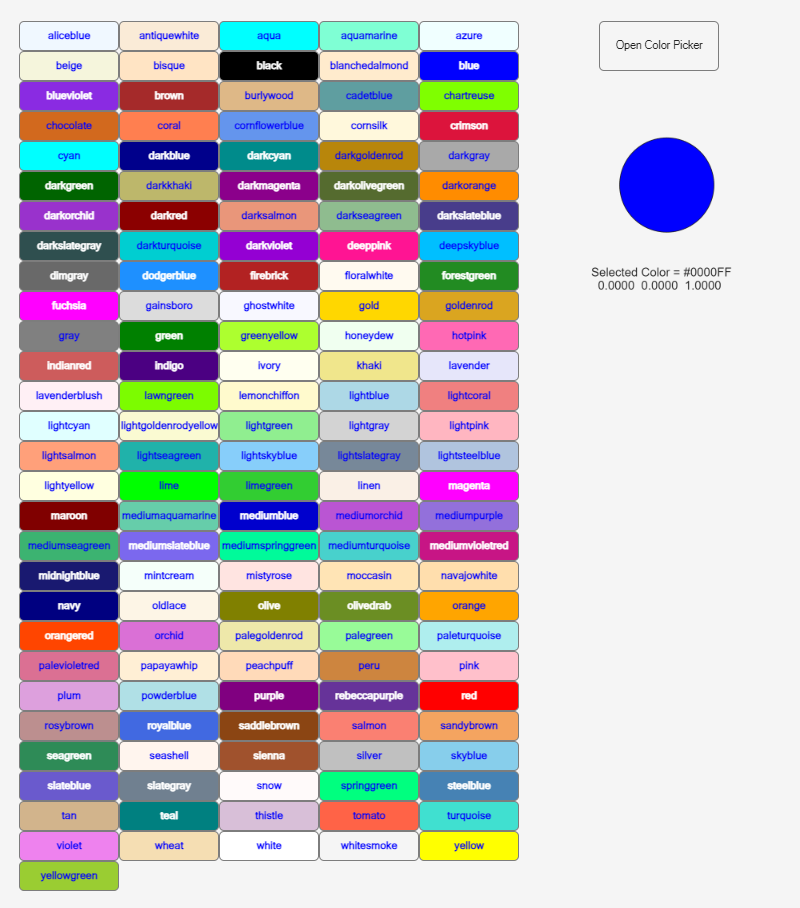

function customColorPicker()
    % Define custom colors
    webcolor = createWebColorStruct();

    colorNames = fieldnames(webcolor);
    customColors = struct2cell(webcolor);
    numColors = length(customColors);

    dh = 30;
    h = floor(dh * (numColors + 2) / 5);

    % Create a figure
    f = figure('Position', [0, 0, 800, h+50]);

    % Draw circle
    ax = uiaxes(f,'Position',[600 h-200 120 120]);
    rect = rectangle(ax,'Position',[0.25 0.25 0.5 0.5], ...
                'Curvature',[1 1],FaceColor="b");
    axis(ax,"equal")
    axis(ax,"off")

    str1 = sprintf('Selected Color = %s',rgb2hex(rect.FaceColor));  % R2024a later
    str2 = sprintf('  %.4f',rect.FaceColor);
    text(600, h-200-130, {str1; str2}, "FontSize",100)
    t = text(0.1, 0, {str1; str2}, "FontSize",12);

    % Create buttons for each custom color
    for i = 1:numColors
        x = mod(i-1,5)  * 100 + 20;
        y = h - floor((i-1)/5) * dh; 
        if (hex2rgb(customColors{i}) * [0.3 0.6 0.1]') > 0.5
            fcol = 'b';
        else
            fcol = 'w';
        end
        uicontrol('Style', 'pushbutton', ...
                  'BackgroundColor', customColors{i}, ...
                  'ForegroundColor', fcol, ...
                  'FontWeight','bold', ...
                  'String', colorNames{i}, ...
                  'Position', [x, y, 100, dh], ...
                  'Callback', @(src, event) selectColor(customColors{i}, rect, t));
    end

    % Create a ColorPicker button
    uicontrol('Style', 'pushbutton', ...
              'String', 'Open Color Picker', ...
              'Position', [600, h-20, 120, 50], ...
              'Callback', @(src, event) openColorPicker(rect, t));
end

function selectColor(color, rect, t)
    rect.FaceColor = color;
    % fprintf('Selected Color = %s\n',color);
    % fprintf('%.4f ',validatecolor(color));  % R2020b later
    % fprintf(newline)
    str1 = sprintf('Selected Color = %s',color);
    str2 = sprintf('  %.4f',validatecolor(color));  % R2020b later
    t.String = {str1; str2};
    
end

function openColorPicker(rect, t)
    color = uisetcolor();
    if sum(color) ~= 0
        disp(['Picked Color: ', num2str(color)]);
        rect.FaceColor = color;

        str1 = sprintf('Selected Color = %s',rgb2hex(color));  % R2024a later
        str2 = sprintf('  %.4f',validatecolor(color));  % R2020b later
        t.String = {str1; str2};
    end
end

% Run the custom color picker
customColorPicker();

function webColor = createWebColorStruct()
    webColor.aliceblue = "#f0f8ff";
    webColor.antiquewhite = "#faebd7";
    webColor.aqua = "#00ffff";
    webColor.aquamarine = "#7fffd4";
    webColor.azure = "#f0ffff";
    webColor.beige = "#f5f5dc";
    webColor.bisque = "#ffe4c4";
    webColor.black = "#000000";
    webColor.blanchedalmond = "#ffebcd";
    webColor.blue = "#0000ff";
    webColor.blueviolet = "#8a2be2";
    webColor.brown = "#a52a2a";
    webColor.burlywood = "#deb887";
    webColor.cadetblue = "#5f9ea0";
    webColor.chartreuse = "#7fff00";
    webColor.chocolate = "#d2691e";
    webColor.coral = "#ff7f50";
    webColor.cornflowerblue = "#6495ed";
    webColor.cornsilk = "#fff8dc";
    webColor.crimson = "#dc143c";
    webColor.cyan = "#00ffff";
    webColor.darkblue = "#00008b";
    webColor.darkcyan = "#008b8b";
    webColor.darkgoldenrod = "#b8860b";
    webColor.darkgray = "#a9a9a9";
    webColor.darkgreen = "#006400";
    webColor.darkkhaki = "#bdb76b";
    webColor.darkmagenta = "#8b008b";
    webColor.darkolivegreen = "#556b2f";
    webColor.darkorange = "#ff8c00";
    webColor.darkorchid = "#9932cc";
    webColor.darkred = "#8b0000";
    webColor.darksalmon = "#e9967a";
    webColor.darkseagreen = "#8fbc8f";
    webColor.darkslateblue = "#483d8b";
    webColor.darkslategray = "#2f4f4f";
    webColor.darkturquoise = "#00ced1";
    webColor.darkviolet = "#9400d3";
    webColor.deeppink = "#ff1493";
    webColor.deepskyblue = "#00bfff";
    webColor.dimgray = "#696969";
    webColor.dodgerblue = "#1e90ff";
    webColor.firebrick = "#b22222";
    webColor.floralwhite = "#fffaf0";
    webColor.forestgreen = "#228b22";
    webColor.fuchsia = "#ff00ff";
    webColor.gainsboro = "#dcdcdc";
    webColor.ghostwhite = "#f8f8ff";
    webColor.gold = "#ffd700";
    webColor.goldenrod = "#daa520";
    webColor.gray = "#808080";
    webColor.green = "#008000";
    webColor.greenyellow = "#adff2f";
    webColor.honeydew = "#f0fff0";
    webColor.hotpink = "#ff69b4";
    webColor.indianred = "#cd5c5c";
    webColor.indigo = "#4b0082";
    webColor.ivory = "#fffff0";
    webColor.khaki = "#f0e68c";
    webColor.lavender = "#e6e6fa";
    webColor.lavenderblush = "#fff0f5";
    webColor.lawngreen = "#7cfc00";
    webColor.lemonchiffon = "#fffacd";
    webColor.lightblue = "#add8e6";
    webColor.lightcoral = "#f08080";
    webColor.lightcyan = "#e0ffff";
    webColor.lightgoldenrodyellow = "#fafad2";
    webColor.lightgreen = "#90ee90";
    webColor.lightgray = "#d3d3d3";
    webColor.lightpink = "#ffb6c1";
    webColor.lightsalmon = "#ffa07a";
    webColor.lightseagreen = "#20b2aa";
    webColor.lightskyblue = "#87cefa";
    webColor.lightslategray = "#778899";
    webColor.lightsteelblue = "#b0c4de";
    webColor.lightyellow = "#ffffe0";
    webColor.lime = "#00ff00";
    webColor.limegreen = "#32cd32";
    webColor.linen = "#faf0e6";
    webColor.magenta = "#ff00ff";
    webColor.maroon = "#800000";
    webColor.mediumaquamarine = "#66cdaa";
    webColor.mediumblue = "#0000cd";
    webColor.mediumorchid = "#ba55d3";
    webColor.mediumpurple = "#9370db";
    webColor.mediumseagreen = "#3cb371";
    webColor.mediumslateblue = "#7b68ee";
    webColor.mediumspringgreen = "#00fa9a";
    webColor.mediumturquoise = "#48d1cc";
    webColor.mediumvioletred = "#c71585";
    webColor.midnightblue = "#191970";
    webColor.mintcream = "#f5fffa";
    webColor.mistyrose = "#ffe4e1";
    webColor.moccasin = "#ffe4b5";
    webColor.navajowhite = "#ffdead";
    webColor.navy = "#000080";
    webColor.oldlace = "#fdf5e6";
    webColor.olive = "#808000";
    webColor.olivedrab = "#6b8e23";
    webColor.orange = "#ffa500";
    webColor.orangered = "#ff4500";
    webColor.orchid = "#da70d6";
    webColor.palegoldenrod = "#eee8aa";
    webColor.palegreen = "#98fb98";
    webColor.paleturquoise = "#afeeee";
    webColor.palevioletred = "#db7093";
    webColor.papayawhip = "#ffefd5";
    webColor.peachpuff = "#ffdab9";
    webColor.peru = "#cd853f";
    webColor.pink = "#ffc0cb";
    webColor.plum = "#dda0dd";
    webColor.powderblue = "#b0e0e6";
    webColor.purple = "#800080";
    webColor.rebeccapurple = "#663399";
    webColor.red = "#ff0000";
    webColor.rosybrown = "#bc8f8f";
    webColor.royalblue = "#4169e1";
    webColor.saddlebrown = "#8b4513";
    webColor.salmon = "#fa8072";
    webColor.sandybrown = "#f4a460";
    webColor.seagreen = "#2e8b57";
    webColor.seashell = "#fff5ee";
    webColor.sienna = "#a0522d";
    webColor.silver = "#c0c0c0";
    webColor.skyblue = "#87ceeb";
    webColor.slateblue = "#6a5acd";
    webColor.slategray = "#708090";
    webColor.snow = "#fffafa";
    webColor.springgreen = "#00ff7f";
    webColor.steelblue = "#4682b4";
    webColor.tan = "#d2b48c";
    webColor.teal = "#008080";
    webColor.thistle = "#d8bfd8";
    webColor.tomato = "#ff6347";
    webColor.turquoise = "#40e0d0";
    webColor.violet = "#ee82ee";
    webColor.wheat = "#f5deb3";
    webColor.white = "#ffffff";
    webColor.whitesmoke = "#f5f5f5";
    webColor.yellow = "#ffff00";
    webColor.yellowgreen = "#9acd32";
end